# GeoPlot Environmental Data

This program plots the environmental data from the SHARC Buoys along with the SA Agulhas II's temperature data for comparison.

## Import Raw Geographical Data 

projectdir = "C:\Users\uctsh\Documents\MATLAB\GPSData\";



## Import Ship Data

shipData = readtable("SCALE-WIN22-SDS_10min.csv");
%Remove times before SB04 deployment
shipData = shipData(shipData.TIME_SERVER> datetime(2022, 07, 20, 15, 40, 00), :);
shipData = shipData(shipData.TIME_SERVER< datetime(2022, 07, 24, 7, 50, 00), :);


## SB04 GPS and Environmental Preprocessing

gpsfileSB04 = fullfile(projectdir, "SB04_GPS_Local.txt"); 
%GPS Data
SB04 = readtable(gpsfileSB04);
Device = 4*ones(height(SB04), 1); 
SB04 = addvars(SB04, Device, 'before', "TimeUTC"); 
%Filter out null GPS values
SB04 = SB04(SB04.("Latitude") < 0.0, :);

%Wave Parameters 
SB04_ENV = readtable("SB04_ENV.txt");
%Note 17:09 20/07/2022 was defined as sample no 1

%Add sample no. to wave parameters
SB04_ENV.sampleNo = (1:height(SB04_ENV)).';

%Remove all null wave parameters
SB04_ENV = rmmissing(SB04_ENV);

%Remove all samples before sample no 1
SB04 = SB04(SB04.DateTimeUTC > datetime(2022, 07, 20, 15, 40, 00), :);

%Note Sample 100 @ 12:54 on 23/07/2022 does not have an associated  GPS data
%point

SB04_ENV(199, :) = [];

%Create array of interpolated GPS Data (midpoint method )
%SB06 Env data bookended wave samples and can each be associated with a 
%GPS Point. therefore - no interpolation


## SB06 GPS and Environmental Preprocessing

gpsfileSB06 = fullfile(projectdir, "SB06_GPS_Local.txt"); 
%GPS Data
SB06 = readtable(gpsfileSB06);
Device = 6*ones(height(SB06), 1); 
SB06 = addvars(SB06, Device, 'before', "TimeUTC"); 
%Filter out null GPS values
SB06 = SB06(SB06.("Latitude") < 0.0, :);

%Wave Parameters 
SB06_ENV = readtable("SB06_ENV.txt");
%Note 17:09 20/07/2022 was defined as sample no 1

%Add sample no. to wave parameters
SB06_ENV.sampleNo = (1:height(SB06_ENV)).';

%Remove all null wave parameters
SB06_ENV = rmmissing(SB06_ENV);

SB06_ENV = SB06_ENV(SB06_ENV.DateTimeUTC > datetime(2022, 07, 20, 19, 30, 00), :);

%Remove all samples before sample no 1
SB06 = SB06(SB06.DateTimeUTC > datetime(2022, 07, 20, 19, 30, 00), :);

%Create array of interpolated GPS Data (midpoint method ) TODO: More
%advanced method


## Plot Individual

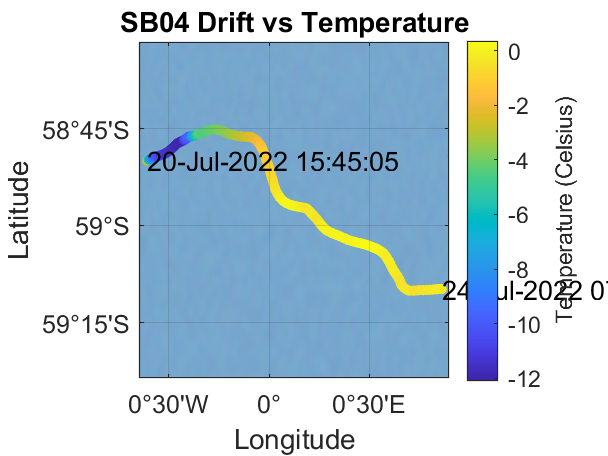

geoscatter(SB04.Latitude, SB04.Longitude, 15, SB04_ENV.Temperature, "filled");
title("SB04 Drift vs Temperature")
text(SB04.Latitude(end), SB04.Longitude(end), string(SB04.("DateTimeUTC")(end)))
text(SB04.Latitude(1), SB04.Longitude(1), string(SB04.("DateTimeUTC")(1)))
geobasemap colorterrain
c = colorbar;
c.Label.String = "Temperature (Celsius)";

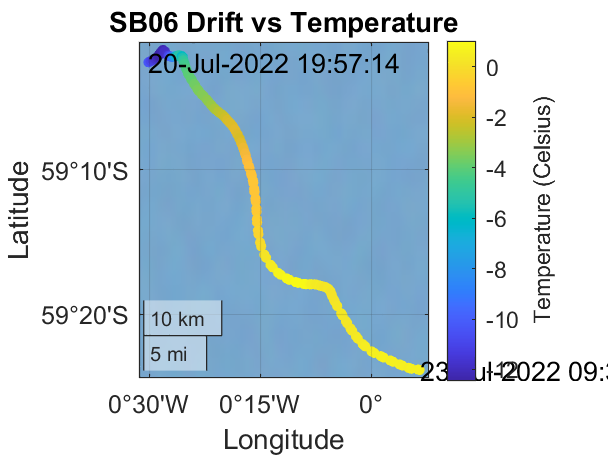



geoscatter(SB06.Latitude, SB06.Longitude, 15, SB06_ENV.Temperature, "filled");
title("SB06 Drift vs Temperature")
text(SB06.Latitude(end), SB06.Longitude(end), string(SB06.("DateTimeUTC")(end)))
text(SB06.Latitude(1), SB06.Longitude(1), string(SB06.("DateTimeUTC")(1)))
geobasemap colorterrain
c = colorbar;
c.Label.String = 'Temperature (Celsius)';

## Plot Combined

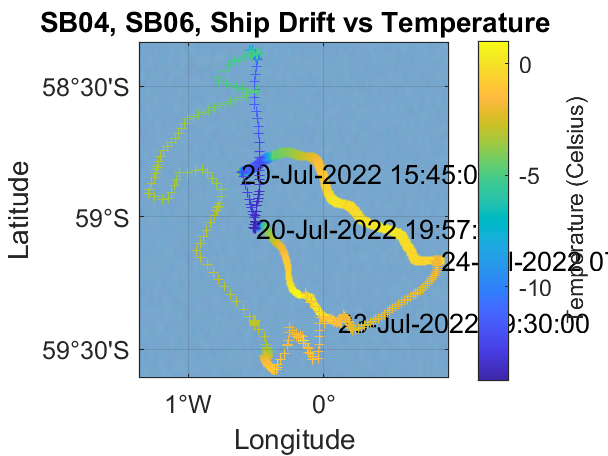

geoscatter(SB04.Latitude, SB04.Longitude, 15, SB04_ENV.Temperature, "filled", "square");
title("SB04, SB06, Ship Drift vs Temperature")
text(SB04.Latitude(end), SB04.Longitude(end), string(SB04.("DateTimeUTC")(end)))
text(SB04.Latitude(1), SB04.Longitude(1), string(SB04.("DateTimeUTC")(1)))
geobasemap colorterrain
c = colorbar;
c.Label.String = "Temperature (Celsius)";
hold on
geoscatter(SB06.Latitude, SB06.Longitude, 10, SB06_ENV.Temperature, "filled", "square");
text(SB06.Latitude(end), SB06.Longitude(end), string(SB06.("DateTimeUTC")(end)))
text(SB06.Latitude(1), SB06.Longitude(1), string(SB06.("DateTimeUTC")(1)))
hold on 
geoscatter(shipData.LAT_DEC, shipData.LON_DEC, 15, shipData.AIR_TEMPERATURE, "+");